# 3. Building Classification Models

## Supervised Learning

Course Example: Heart Disease

% Load the example data
load('heartdisease.mat')
% Is it necessary to apply a classification model to the data?
% Pre-evaluation of the data
[g, c] = kmeans(zscore(heartdataNum{:,1:11}),2); %그룹을 2개로 나누다 
counts = crosstab(g,heartdataNum.HeartDisease)

counts =     66   165
   125    71


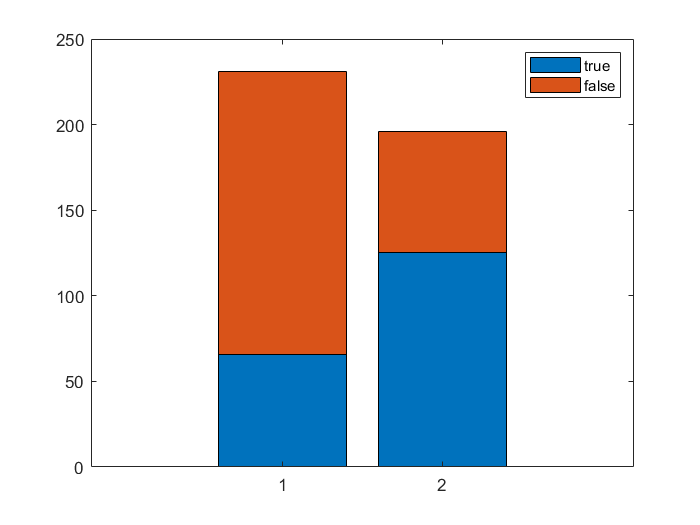

figure
bar(counts,'stacked')
legend([{'true'},{'false'}])

### Training and Validation

% Divide the heart disease into training(80%) and validation(20%) sets
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2) %validation set 20% 

part = 홀드아웃 교차 검증 분할
   NumObservations: 427
       NumTestSets: 1
         TrainSize: 342
          TestSize: 85

tridx = training(part);
tdata = heartdataNum(tridx,:)

tdata = 342×12 table
           Age              Cholesterol       ExerciseDuration      METs     RestingHeartRate      RestingSystolic     RestingDiastolic       MaxHeartRate        PeakExSystolic       PeakExDiastolic        InducedSTDep       HeartDisease
    _________________    _________________    _________________    ______    _________________    _________________    _________________    _________________    _________________    _________________    __________________    ____________

    0.708333333333333    0.371508379888268    0.486486486486487    0.6875    0.253164556962025    0.490740740740741    0.583333333333333    0.609022556390977     0.67948717948718    0.615384615384615     0.410714285714286       false    
    0.791666666666667    0.519553072625698    0.432432432432432    0.6875     0.30379746835443     0.62962962962963    0.666666666666667    0.293233082706767    0.487179487179487    0.615384615384615     0.267857142857143       true     
    0.166666666666667    0

vdata = heartdataNum(~tridx,:)

vdata = 85×12 table
           Age              Cholesterol       ExerciseDuration      METs     RestingHeartRate      RestingSystolic     RestingDiastolic       MaxHeartRate        PeakExSystolic       PeakExDiastolic        InducedSTDep       HeartDisease
    _________________    _________________    _________________    ______    _________________    _________________    _________________    _________________    _________________    _________________    __________________    ____________

    0.791666666666667    0.360335195530726    0.378378378378378       0.5    0.481012658227848    0.259259259259259                  0.5    0.451127819548872    0.358974358974359    0.519230769230769     0.464285714285714       true     
    0.708333333333333    0.430167597765363    0.351351351351351    0.4375    0.443037974683544    0.351851851851852    0.916666666666667    0.586466165413534    0.230769230769231    0.423076923076923                  0.25       true     
    0.583333333333333    0.

tdataAll = heartdataAll(tridx,:);
vdataAll = heartdataAll(~tridx,:)

vdataAll = 85×22 table
           Age              Cholesterol       ExerciseDuration      METs     RestingHeartRate      RestingSystolic     RestingDiastolic       MaxHeartRate        PeakExSystolic       PeakExDiastolic        InducedSTDep       Sex     ChestPainType      BloodSugar      RestingECG      BetaBlockerUsed    NitratesUsed    CaChanBlockerUsed    DiureticUsed    ExInducedAngina    STSlope    HeartDisease
    _________________    _________________    _________________    ______    _________________    _________________    _________________    _________________    _________________    _________________    __________________    ___    ________________    __________    ______________    _______________    ____________    _________________    ____________    _______________    _______    ____________

    0.791666666666667    0.360335195530726    0.378378378378378       0.5    0.481012658227848    0.259259259259259                  0.5    0.451127819548872    0.358974358974359

### 1. Nearest Neighbor Classification(1/2)

The most straightforward way of classification without any assumptions about the underlying distribution of the data

m = fitcknn(tdata,'HeartDisease');

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


% Why use tdata, not tdataAll? because k-NN does not accept mixed predictors(numeric+categorical).

### Evaluating Classifications

m = fitcknn(tdata,'HeartDisease')

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


% Measure loss
errKNN_train = resubLoss(m) % Measure loss with the training data , To check Overfiting problem 

errKNN_train =      0


errKNN_test = loss(m,vdata)% Measure loss with the test(validation) data

errKNN_test =    0.341265397536394



% Visualize prediction accuracy
HDpred = predict(m,vdata)

HDpred = 85×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 


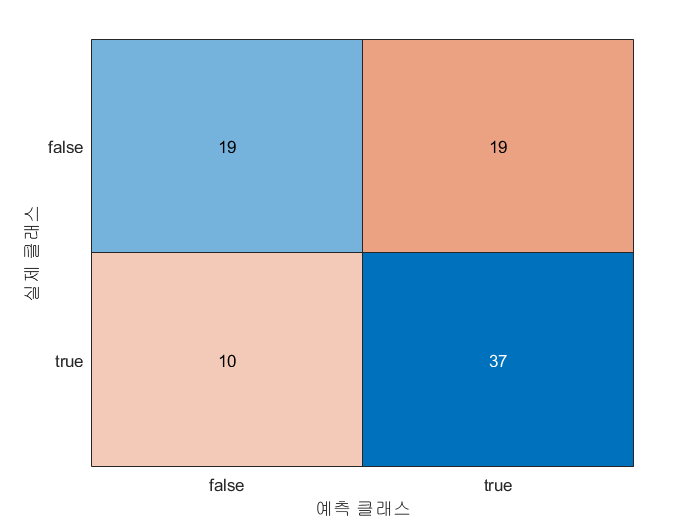

HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred) % blue is coreect, red is incorrect 

### 1. Nearest Neighbor Classification(2/2)

% Check overfitting and Update model 1
m = fitcknn(tdata,'HeartDisease',"NumNeighbors",5)

m =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


errKNN_train = resubLoss(m) 

errKNN_train =    0.222222222222222


errKNN_test = loss(m,vdata)

errKNN_test =    0.247126775505393


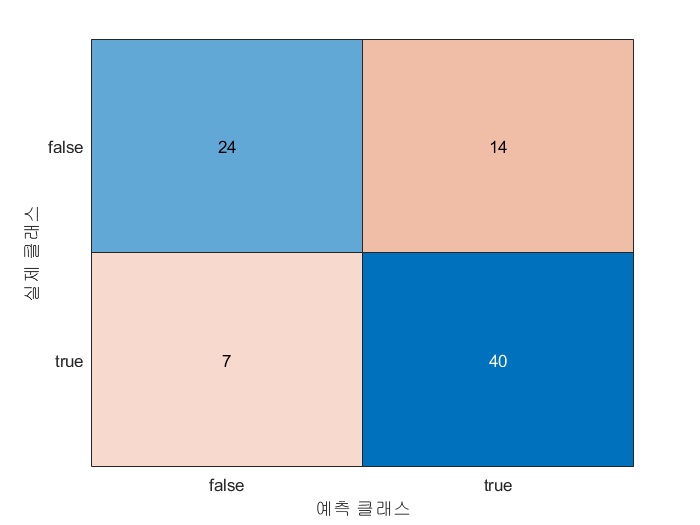

HDpred = predict(m,vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

 
 
% Update model 2
m.DistanceWeight = 'squaredinvers';
errKNN_train = resubLoss(m) 

errKNN_train =      0


errKNN_test = loss(m,vdata)

errKNN_test =    0.247126775505393


### 2. Decision Tree Classification

A decision tree model make a categorical response prediction by following a sequence of binary decisions based on predictor variable value. It does not assume any underlying distributions of the data like k-NN.

A decision tree model is robust to noise data.

% Fit and evaluate a decision tree model with default settings
m = fitctree(tdata, 'HeartDisease');
%view(m,'Mode','graph');

errDT_train = resubLoss(m)

errDT_train =    0.078947368421053


errDT_test = loss(m,vdata)

errDT_test =    0.282371662639241


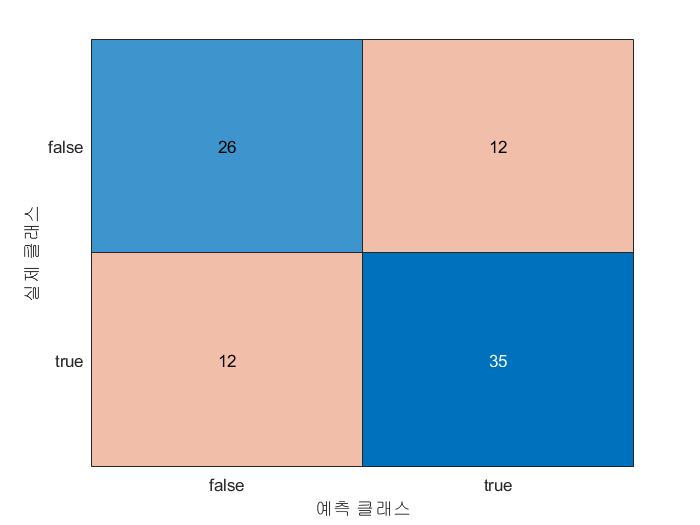

HDpred = predict(m,vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

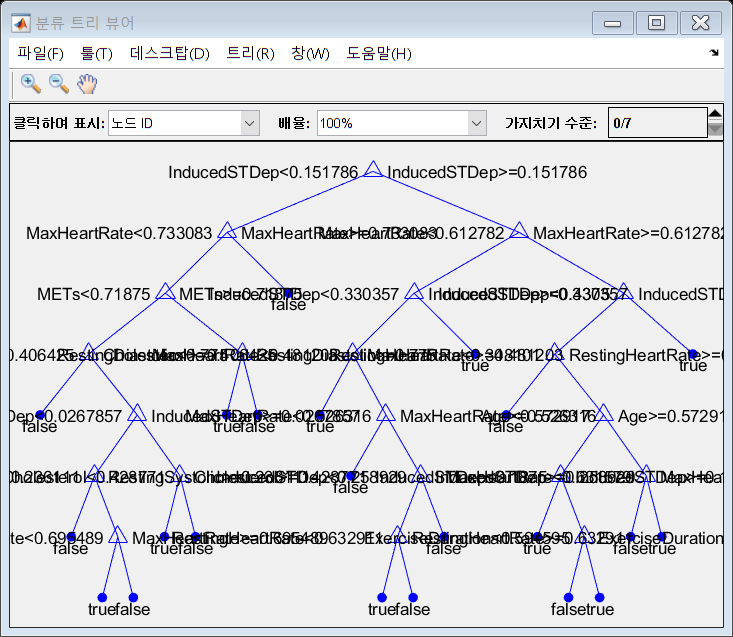


% Check overfitting and update model with 'prune' function
m = prune(m,'Level',3);
view(m,'Mode','graph')

errPruneDT_train = resubLoss(m)

errPruneDT_train =    0.140350877192982


errPruneDT_test = loss(m,vdata)

errPruneDT_test =    0.200035362763010



% Unlike k-NN, a decision tree model accepts mixed data(numeric + categorical)
m = fitctree(tdataAll, 'HeartDisease')

m =   ClassificationTree
           PredictorNames: {1×21 cell}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: [12 13 14 15 16 17 18 19 20 21]
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


errDT_train = resubLoss(m)

errDT_train =    0.055555555555556


errDT_test = loss(m,vdataAll)

errDT_test =    0.235309718866034



m = prune(m,'Level',3);
errPruneDT_train = resubLoss(m)

errPruneDT_train =    0.108187134502924


errPruneDT_test = loss(m,vdataAll)

errPruneDT_test =    0.211793481464018


### 3. Naive Bayes Classification

A Naive Bayes model uses Bayes's rule of conditional probability to estimate the probability of a given observation being in each response class. Accordingly, it assumes an underlying distribution of the data. (Note: Each predictor variable should be independent, If not, use a 'Discriminant Analysis')

m = fitcnb(tdata,'HeartDisease')

m =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


errNB_train = resubLoss(m)

errNB_train =    0.298245614035088


errNB_test = loss(m,vdata) 

errNB_test =    0.200020628278423



% Use kernel smoothing instead of normal distributions
% Kernel smoothing only works for numeric predictor variables
m = fitcnb(tdata,'HeartDisease','DistributionNames',"kernel")

m =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×11 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'  'unbounded'}
                     Width: [2

errNB_train = resubLoss(m)

errNB_train =    0.260233918128655


errNB_test = loss(m,vdata)

errNB_test =    0.176504390876407





% Use a mix of numeric and categorical predictors and use kernel smoothing for all numerical predictors
m = fitcnb(tdataAll, 'HeartDisease');
errNB_train = resubLoss(m)

errNB_train =    0.204678362573099


errNB_test = loss(m,vdataAll) 

errNB_test =    0.117669593917605



dists = [repmat({'kernel'},1,11),repmat({'mvmn'},1,10)]

dists = 1×21 cell 배열
    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}


%dists2 = repmat({'mvmn'},1,10)
m = fitcnb(tdataAll, 'HeartDisease','DistributionNames',dists)

m =   ClassificationNaiveBayes
            PredictorNames: {1×21 cell}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: [12 13 14 15 16 17 18 19 20 21]
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'  'mvmn'}
    DistributionParameters: {2×21 cell}
         CategoricalLevels: {[]  []  []  []  []  []  []  []  []  []  []  [2×1 double]  [4×1 double]  [2×1 double]  [3×1 double]  [2×1 double]  [2×1 double]  [2×1 double]  [2×1 double]  [2×1 double]  [3×1 double]}
                    Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  []  []  []  []  []  []  []  []  []  []}
       

errNB_train = resubLoss(m)

errNB_train =    0.195906432748538


errNB_test = loss(m, vdataAll)

errNB_test =    0.141200565804208
